% TASK 1:
% Load the image and convert pixel values to a double-precision range of [0, 1] [cite: 91, 93, 99]
I = imread('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Lab07\flower.jpg');
I = im2double(I);
figure, imshow(I)
whos I

  Name        Size                 Bytes  Class     Attributes

  I         500x351x3            4212000  double              




[R, G, B] = imsplit(I);
whos R

  Name        Size               Bytes  Class     Attributes

  R         500x351            1404000  double              




W = 5;
h = ones(W) ./ W.^2;

% Apply 2D convolution to each color plane to blur
Ravg = conv2(R, h, "same"); 
Gavg = conv2(G, h, "same");
Bavg = conv2(B, h, "same");

Iavg = cat(3, Ravg, Gavg, Bavg); 
whos Iavg 

  Name        Size                 Bytes  Class     Attributes

  Iavg      500x351x3            4212000  double              



figure, imshow(Iavg, [])

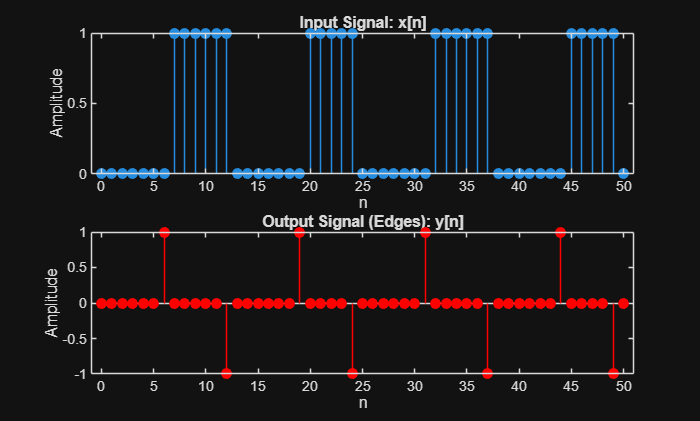

%% Task 2:
n = 0:50;

% Creating the input signal
x = double((sin(0.5*n) + 0.2) < 0); 

% Defining the first difference filter impulse response
h = [1, -1];
y = conv(x, h, 'same'); 

figure;
subplot(2,1,1);
stem(n, x, 'filled');
title('Input Signal: x[n]');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(n, y, 'filled', 'r');
title('Output Signal (Edges): y[n]');
xlabel('n'); ylabel('Amplitude');

The first-difference filter, defined by the impulse response, acts as a basic edge detector. By comparing the current value of the signal to its previous value, the filter identifies transitions in the input.

**Positive Spikes:** A value of +1 in the output indicates a transition from 0 to 1. 

**Negative Spikes:** A value of -1 in the output indicates a transition from 1 to 0.

**Zero Values:** When the signal is constant (all 0 or all 1s), the output is 0 because there is no change between adjacent samples.

%% Task 3: Edge Detection on Image Data

% Load the echart matrix
load('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Lab07\echart.mat');

% Display the original image
figure;
imshow(echart); 
title('Original E-Chart Image');

% This treats one line of the image as a 1D signal 
row_idx = 65;
x = echart(row_idx, :);

% Apply the first difference filter
h = [1, -1];
y = conv(double(x), h, 'same'); 

% Visualization: Compare Input vs. Output
figure;
subplot(2,1,1);
stem(x, 'Marker', 'none');
title(['Input Signal: Row ', num2str(row_idx)]);
xlabel('Column Index (n)'); ylabel('Intensity');

subplot(2,1,2);
stem(y, 'Marker', 'none', 'Color', 'r');
title('Output Signal: First Difference (Edges)');
xlabel('Column Index (n)'); ylabel('Amplitude');


## **What do the 0s and 255s represent in the input?**

In the grayscale echart image, 0 represents black pixels and 255 represents white pixels.

## **What do the non-zero values represent in the output y[n]?**

The non-zero values represent edges. A non-zero value occurs only when there is a change in intensity between adjacent pixels (e.g., switching from the white background to a black letter)

%% Task 4: Bar Code Detection

% Read the image and extract a middle row
img = imread('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Lab07\HP110v3.png');
[rows, cols, ~] = size(img);
mid_row = round(rows/2); % Get the middle row index
x = double(img(mid_row, :)); 

% Applying first Difference filter
h = [1, -1];
y = conv(x, h, 'same');

%Thresholding System
tau = 100; 
d = abs(y) >= tau; % d[n] is 1 at edges, 0 otherwise

% Finding edge locations
locs = find(d); 

% Calculating bar widths
% Difference between consecutive edge locations gives the width of bars
bar_widths = conv(locs, h, 'same'); 
bar_widths = diff(locs); 

% Plotting
figure;
subplot(3,1,1); plot(x); title('Original Barcode Row Signal x[n]');
subplot(3,1,2); plot(y); title('Filtered Signal y[n] (Spikes)');
subplot(3,1,3); stem(bar_widths); title('Calculated Bar Widths (Pixels)');


%% Task 5: Final Decoding
myPath = 'C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Lab07';
addpath(myPath);

% Extract the 59 bars starting from the 1-1-1 guard pattern
useful_widths = bar_widths(5:63); 

% Normalize to the 95-unit standard
w_bar = sum(useful_widths) / 95;
delta_fixed = round(useful_widths / w_bar);

% Force the sum to 95
% If the sum is 96, we will find the largest bar and shrink it by 1.
% If the sum is 94, we find the largest bar and grow it by 1.
while sum(delta_fixed) > 95
    [~, idx] = max(delta_fixed);
    delta_fixed(idx) = delta_fixed(idx) - 1;
end
while sum(delta_fixed) < 95
    [~, idx] = max(delta_fixed);
    delta_fixed(idx) = delta_fixed(idx) + 1;
end

% 4. Final Decoding
barcode_result = decodeUPC(delta_fixed);

ssbeg =      1     1     1


disp('The decoded barcode is:');

The decoded barcode is:


disp(barcode_result);

     8     8     2     7     8     0     4     5     0     1     6     5



RUBRIC: